clc; clear; close all; format long g;

## Reading data

[ v] = readvars('p213resxt.xlsx');
t = 1:length(v);
%t = juliandate(time, 'modifiedjuliandate');

## GAPFilling

## Wavelete transform

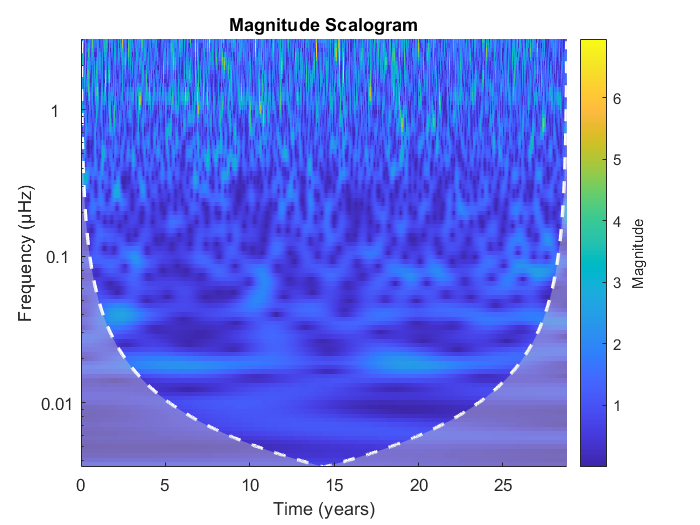

h1 = figure(1) ;
fs = 1/(24*16.843258*365.25) ;
cwt(v, fs)

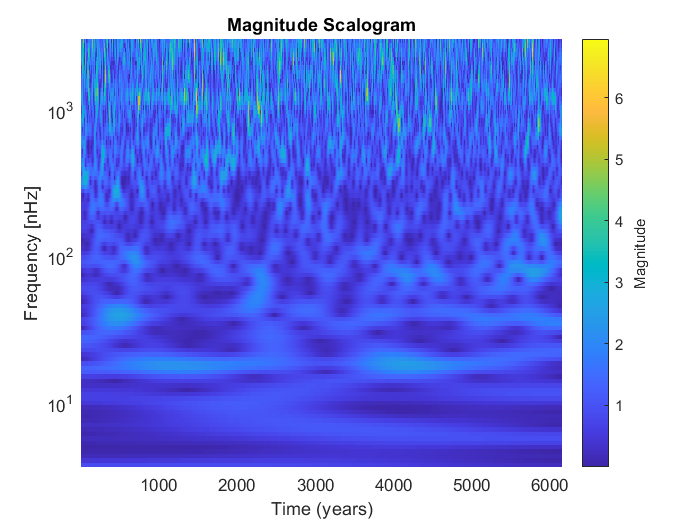

%16.843258
h2 = figure(2) ;

[wt, f] = cwt(v, fs) ;

f = f*1e9 ;
image('XData',t,'YData',f,'CData',abs(wt),'CDataMapping','scaled')
axis tight
set(gca, 'YScale', 'log')
xlabel('Time (years)') ;
ylabel('Frequency [nHz]')
title('Magnitude Scalogram')
c = colorbar ;
c.Label.String = 'Magnitude' ;

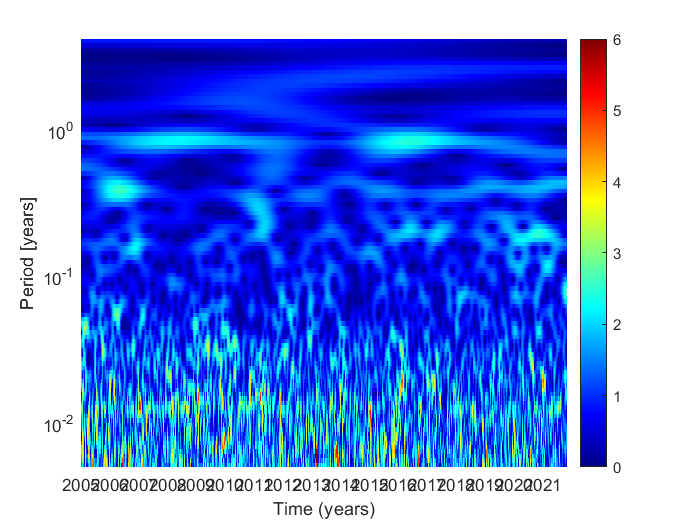


h3 = figure(3) ;

f = f*1e-9;
period = (1./f)/24*365.25 ;
image('XData',t,'YData',period*1e-9,'CData',abs(wt),'CDataMapping','scaled')
axis tight
set(gca, 'YScale', 'log')
xlabel('Time (years)') ;
ylabel('Period [years]')
c = colorbar ;
c.Label.String = 'Magnitude' ;

XTickLabel = 2005:1:2022 ;
XTick = t(1):365.25:t(end);
%(XTickLabel-t(1))
set(gca, 'XTick', XTick)
set(gca, 'XTickLabel', XTickLabel)

c = colorbar ; colormap jet; caxis([0 6]);

## Plot Yline

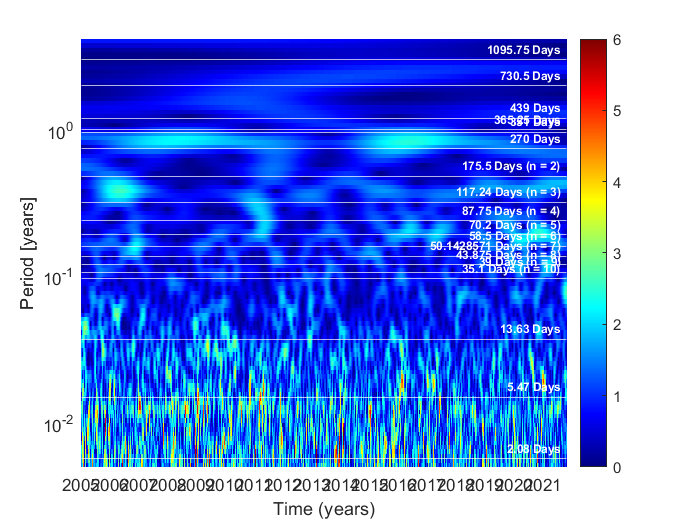

yline((1)/(365.25/270),'-',"270 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/365.25),'-',"365.25 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/2.08),'-',"2.08 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/730.5),'-',"730.5 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/439),'-',"439 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/351),'-',"351 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/175.5),'-',"175.5 "+"Days (n = 2)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/117.24),'-',"117.24 "+"Days (n = 3)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/87.75),'-',"87.75 "+"Days (n = 4)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/70.2),'-',"70.2 "+"Days (n = 5)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/58.5),'-',"58.5 "+"Days (n = 6)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/50.1428571),'-',"50.1428571 "+"Days (n = 7)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/43.875),'-',"43.875 "+"Days (n = 8)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/39),'-',"39 "+"Days (n = 9)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/35.1),'-',"35.1 "+"Days (n = 10)",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/5.47),'-',"5.47 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/13.63),'-',"13.63 "+"Days",'fontweight','bold','fontsize',7,'color','w')
yline((1)/(365.25/1095.75),'-',"1095.75 "+"Days",'fontweight','bold','fontsize',7,'color','w')

## plot Xline

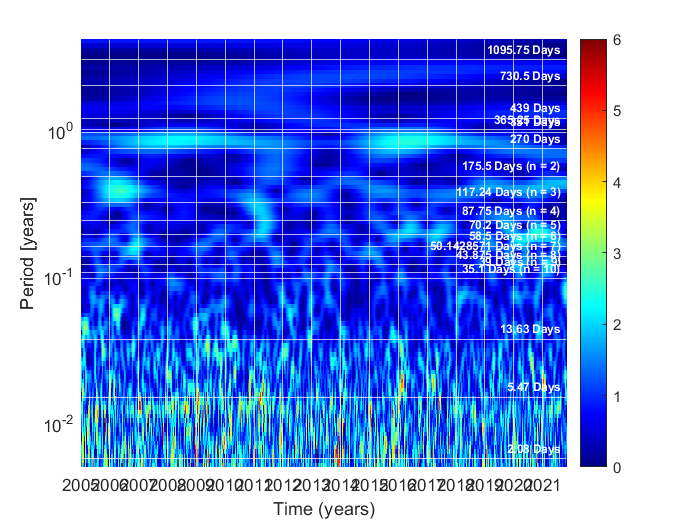

xline(365.25,'-','fontweight','bold','fontsize',7,'color','w')
xline(730,'-','fontweight','bold','fontsize',7,'color','w')
xline(1095.75,'-','fontweight','bold','fontsize',7,'color','w')
xline(1461,'-','fontweight','bold','fontsize',7,'color','w')
xline(1826.25,'-','fontweight','bold','fontsize',7,'color','w')
xline(2556.75,'-','fontweight','bold','fontsize',7,'color','w')
xline(2922,'-','fontweight','bold','fontsize',7,'color','w')
xline(3287.25,'-','fontweight','bold','fontsize',7,'color','w')
xline(3652.5,'-','fontweight','bold','fontsize',7,'color','w')
xline(4017.75,'-','fontweight','bold','fontsize',7,'color','w')
xline(4383,'-','fontweight','bold','fontsize',7,'color','w')
xline(4748.25,'-','fontweight','bold','fontsize',7,'color','w')
xline(5113.5,'-','fontweight','bold','fontsize',7,'color','w')
xline(5478.75,'-','fontweight','bold','fontsize',7,'color','w')
xline(5844,'-','fontweight','bold','fontsize',7,'color','w')
xline(2191.5,'-','fontweight','bold','fontsize',7,'color','w')